## 单带Hubbard模型的能带结构

哈密顿量为


$$H=t\sum_{<i,j>}a_j^\dagger a_i
$$


傅里叶变换到倒空间，自动完成对角化


$$ a_j^\dagger=\frac{1}{\sqrt{N}}\sum_{k}e^{-ik\cdot R_j}a_k^\dagger$$


对于二维方晶格


$$H=\sum_k 2t\left[cos(k_x a)+cos(k_y)a\right]n_k$$


单电子能带结构$E(k)$

clear;close all;
kxa = -pi:0.1:pi;
kya = -pi:0.1:pi;
t = 0.4

t = 0.4000

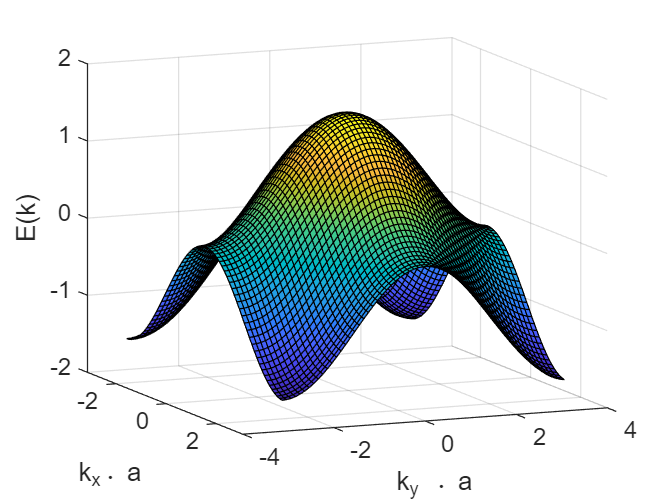

[x,y]=meshgrid(kxa,kya);
E = 2*t*(cos(x)+cos(y));
surf(x,y,E)
view([66.92 12.29])
xlabel('k_x\cdot a')
ylabel('k_y \cdot a')
zlabel('E(k)')


% 波函数图像
L = 20;



$$|k_0>=\frac{1}{\sqrt{N}}\sum_i |R_i>e^{iR_i\cdot k_0}$$



$$<R_j|k_0>=\frac{1}{\sqrt{N}}e^{iR_j\cdot k_0}$$


基态要分情况处理

- 如果 $t<0$, $k_0=(0,0)$

此时波函数（投影到格点上）


$$<R_j|k_0>=\frac{1}{\sqrt{N}}$$


- 如果 $t>0$, $k_0=(\pi/a,\pi/a)$


$$<R_j|k_0>=\frac{1}{\sqrt{N}}e^{i(x_j+y_j)\pi/a}$$


符合哈密顿量的基态能量最低原则

## 两带checkboard littice的Hubbard模型


$$H=\sum_{<l,l'>}\tau_{l,l'}b_l^\dagger b_{l'}$$


包含近邻项的hoping和次近邻项一半的hoping

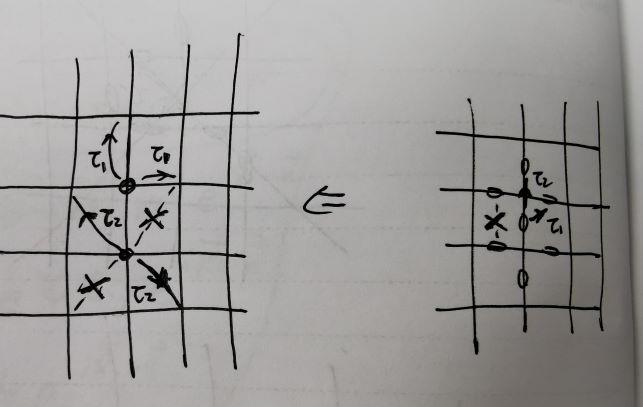

设近邻为 $\tau_1$，次近邻为 $\tau_2$


$$E_{1,2}=2\tau_2\cos{(k_xa)}\cos{(k_ya)}\pm2\sqrt{\tau_2^2\sin^2(k_xa)\sin^2(k_ya)-\tau_1^2\left[\cos(k_xa)+\cos(k_ya)\right]^2}$$


clear;close all;
kxa = -pi:0.1:pi;
kya = -pi:0.1:pi;
tau1 = 0.4

tau1 = 0.4000

tau2 = 0.7

tau2 = 0.7000

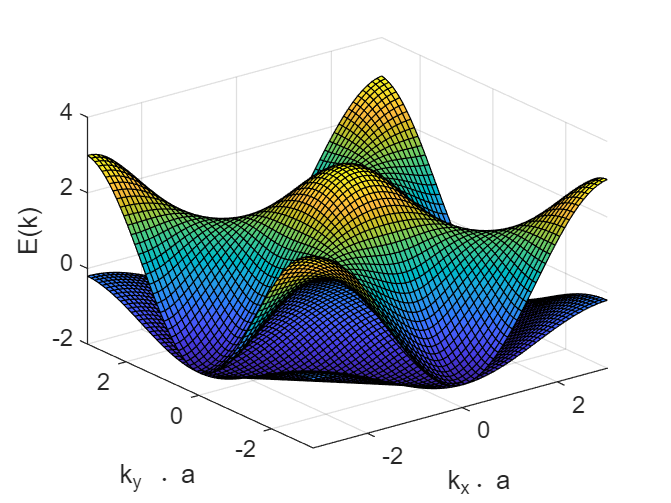

[x,y]=meshgrid(kxa,kya);
Eplus = 2*tau2*cos(x).*cos(y)+2*sqrt(tau2^2*sin(x).^2.*sin(y).^2+tau1^2*(cos(x)+cos(y)).^2);
Eminus= 2*tau2*cos(x).*cos(y)-2*sqrt(tau2^2*sin(x).^2.*sin(y).^2+tau1^2*(cos(x)+cos(y)).^2);
figure
surf(x,y,Eplus)
hold on 
surf(x,y,Eminus)
xlabel('k_x\cdot a')
ylabel('k_y \cdot a')
zlabel('E(k)')

这个结果是在变换表象之后得到的。事实上，在原先表象下，晶格是方晶格，更容易进行相关计算。


$$E=\tau_2\left[\cos(k_xa)+\cos(k_ya)\right]\pm\sqrt{\tau_2^2\left[\cos(k_xa)-\cos(k_ya)\right]^2+4\tau_1^2\left(1+\cos(k_xa)\right)\left(1+\cos(k_ya)\right)}$$


clear;close all;
kxa = -pi:0.1:pi;
kya = -pi:0.1:pi;
tau1 = 0.2

tau1 = 0.2000

tau2 = 0.5

tau2 = 0.5000

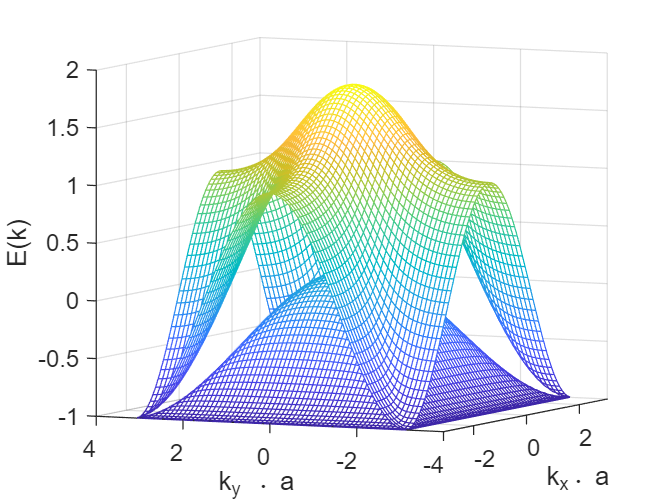

[x,y]=meshgrid(kxa,kya);
Eplus = tau2*(cos(x)+cos(y))+sqrt(tau2^2*(cos(x)-cos(y)).^2+4*tau1^2*(1+cos(x)).*(1+cos(y)));
Eminus= tau2*(cos(x)+cos(y))-sqrt(tau2^2*(cos(x)-cos(y)).^2+4*tau1^2*(1+cos(x)).*(1+cos(y)));
figure
mesh(x,y,Eplus)
hold on 
mesh(x,y,Eminus)
xlabel('k_x\cdot a')
ylabel('k_y \cdot a')
zlabel('E(k)')

view([-64.76 5.96])

在没有相互作用和约束的情况下，粒子将在（0，0）处凝聚。在（0，0） 处粒子的波函数具有特定的相位。我们可以做基底变换，得到s-wave和d-wave。舍弃高能部分，得到低能的有效模型，也就是one-band模型。

利用撒点法求态密度。在第一布里渊区均匀撒点，统计E的分布即可

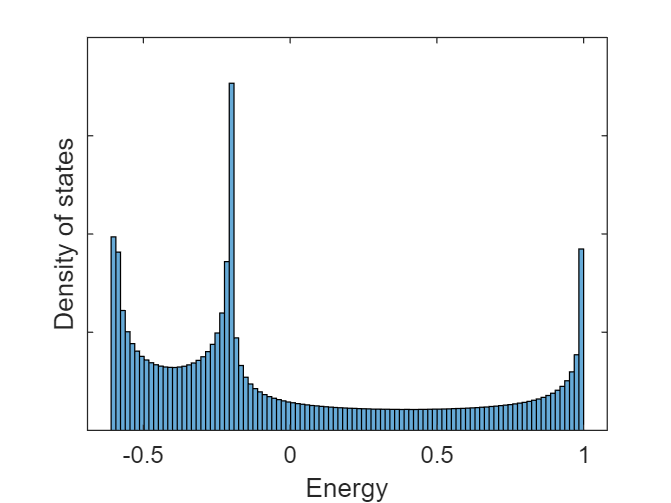

N = 1e5;
Eset = zeros(1,2*N);
for i=1:N
    x = 2*pi*(i/N-0.5);
    y = 2*pi*(i/N-0.5);
    Eset(i) =  tau2*(cos(x)+cos(y))+sqrt(tau2^2*(cos(x)-cos(y)).^2+4*tau1^2*(1+cos(x)).*(1+cos(y)));
    Eset(i+N)= tau2*(cos(x)+cos(y))-sqrt(tau2^2*(cos(x)-cos(y)).^2+4*tau1^2*(1+cos(x)).*(1+cos(y)));
end
figure
histogram(Eset,100,'Normalization','probability')
set(gca,'YTickLabel',[])
xlabel('Energy')
ylabel('Density of states')